## Import Data

clear all;
clc;
data = readtable("step_osc_150ohm.csv");
data = fillmissing(data,'nearest');
data([1,2],:) = [];

## Assign Variables

% Seperate values
t = table2array(data(:,1))+5;
ADC = round(table2array(data(:,2))/30*1024);
OCR = table2array(data(:,3));

% Match to duty cycle
OCR = round(OCR/5)*102+512;

% Find index before step
idx = find(OCR<600,1,'last')

idx = 74


% Trim data with new index
t = t(idx-9:end);
ADC = ADC(idx-9:end);
OCR = OCR(idx-9:end);

% Reset time and find sampling time
t = t-t(1);
T_s=t(2)-t(1)

T_s = 0.0039

## Identify Transfer Functions

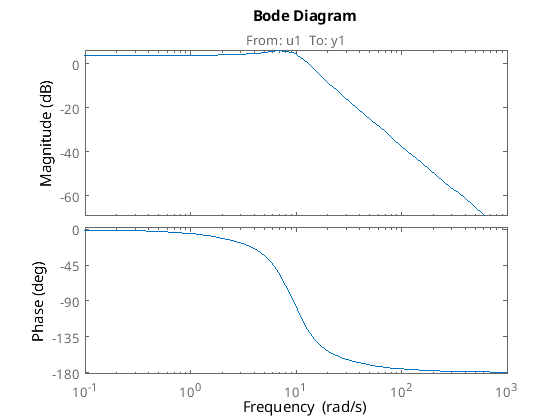

idd = iddata(OCR,ADC,T_s);
G=tfest(idd,2,0);
bode(G)

gm = 60; Ni=3; alpha=0.1;
[wc, Kp, taui, taud, ok] = findpid(G,gm,Ni,alpha);

ans = 'Found 1 valid solution(s) out of 1 phase crossing(s)'

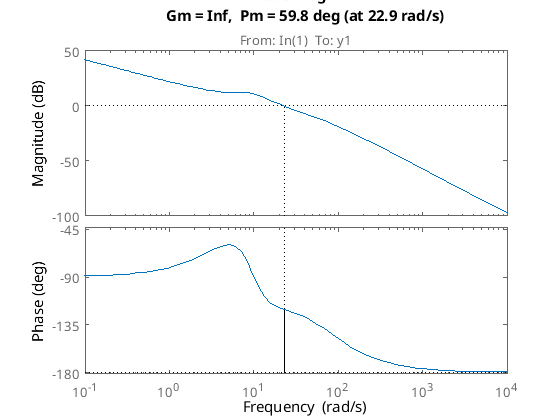

s=tf('s');
Cpid=Kp*(taud*s+1)/(alpha*taud*s+1)*(taui*s+1)/(taui*s);
Cpid = minreal(Cpid);
Gol=minreal(G*Cpid);
margin(Gol);

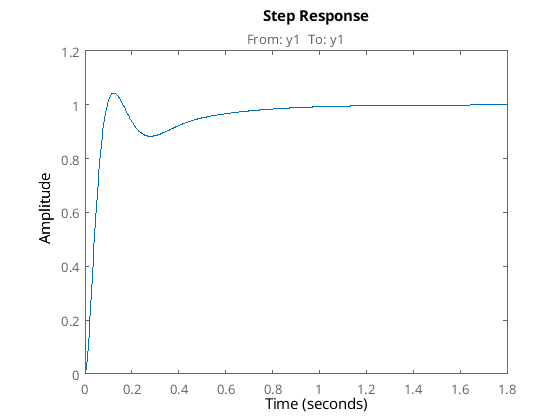

step(Gol/(1+Gol))

## Z-Transform

Gz=c2d(Cpid,1/10e3,'tustin');
Gz.Variable='z^-1'

Gz =
 
  10.49 - 20.96 z^-1 + 10.47 z^-2
  -------------------------------
   1 - 1.993 z^-1 + 0.9928 z^-2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



## Discrete Implementation


$$y_i =22\ldotp 11\cdot u_i -44\ldotp 15\cdot u_{i-1} +22\ldotp 05\cdot u_{i-2} +1\ldotp 996\cdot y_{i-1} -0\ldotp 9959\cdot y_{i-2}$$


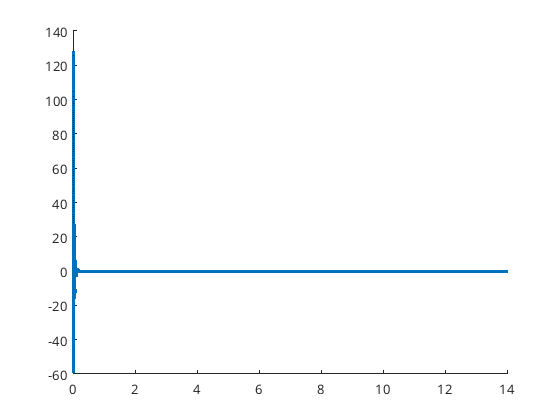

% Build time vector
dt=1/10e3;
t = 0:dt:14;

% Build step input
u = ones(size(t));
u(1)=0;

% Initialize variables
uk_1=0;
uk_2=0;
yk_1=0;
yk_2=0;

% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uvals = 127.3*u(i) - 254*uk_1 + 126.7*uk_2;
        yvals = 1.993*yk_1 - 0.9932*yk_2;
        y(i) = uvals + yvals;
    elseif i == 2
        uvals = 127.3*u(i) - 254*u(i-1) + 126.7*uk_2;
        yvals = 1.993*y(i-1) - 0.9932*yk_2;
        y(i) = uvals + yvals;
    else
        uvals = 127.3*u(i) - 254*u(i-1) + 126.7*u(i-2);
        yvals = 1.993*y(i-1) - 0.9932*y(i-2);
        y(i) = uvals + yvals;
    end
end

scatter(t,y,3)

1/(20/(20+80))

ans = 5